clear all
load fisheriris



[C,ia,ic] = unique(species);

y = [ic==1 ic==2 ic==3];
indexes= randperm(150);

input = normalize(meas(indexes,:),'range')

input =     0.1944    0.5000    0.0339    0.0417
    0.3333    0.1250    0.5085    0.5000
    0.3056    0.7083    0.0847    0.0417
    0.5833    0.5000    0.5932    0.5833
    0.1944    0.6250    0.1017    0.2083
    0.3889    0.3750    0.5424    0.5000
    0.3056    0.4167    0.5932    0.5833
    0.4167    0.2917    0.6949    0.7500
    0.2778    0.7083    0.0847    0.0417
    0.1389    0.5833    0.1525    0.0417


output = y(indexes,:)

output = 150×3 logical array
   1   0   0
   0   1   0
   1   0   0
   0   1   0
   1   0   0
   0   1   0
   0   1   0
   0   0   1
   1   0   0
   1   0   0


% plot(Nr(:,4))
% plot(meas(:,4))

testinput = input((end-49):end,:);
testoutput = output((end-49):end,:);

batchsize = 100;

in = input(1:batchsize,:);
out = output(1:batchsize,:);

n = 2

n = 2

;

% Vandermonde ----------
B=[]


B =

     []



for i = 1:batchsize
    
a=in(i,1).^[0:n];   a = a/norm(a);
b=in(i,2).^[0:n];   b = b/norm(b);
c=in(i,3).^[0:n];   c = c/norm(c);
d=in(i,4).^[0:n];   d = d/norm(d);

f= outproduct(a,b,c,d);
B(i,:)=f(:)';
end
% ----------- ----------


training logistic sigmoid

w = randn([(n+1)^4 3])/100

w =    -0.0106   -0.0063    0.0064
   -0.0101   -0.0096   -0.0188
    0.0078    0.0080    0.0046
   -0.0054    0.0049   -0.0143
    0.0151    0.0289   -0.0011
    0.0101    0.0198    0.0111
   -0.0096    0.0147    0.0104
    0.0037   -0.0041   -0.0089
    0.0073   -0.0271    0.0031
    0.0019    0.0059   -0.0128


w2 = randn([3 3])/100

w2 =    -0.0227    0.0052    0.0122
    0.0093    0.0054    0.0011
    0.0047    0.0083   -0.0069



alpha=0.01

alpha = 0.0100

alpha2=0.01

alpha2 = 10

tic
for i= 1:100
z1 = B*w;
z2 = w2*z1';

expp = exp(z2-max(z2,[],1));
p1 = expp./sum(expp,1);
sum(p1,2);
% a1 = (1+exp(-z1)).^-1;
% d1= a1.*(1-a1).*(a1-out);
% d1= a1.*(1-a1).*((-out./a1)+(1-out)./(1-a1));
sumz=zeros(3,3);
d2 = p1-out';
d1= w2'*d2;
for j=1:batchsize
dw2 = d2(:,j)*z1(j,:);
sumz=sumz-dw2;
end
w2 = w2-alpha*alpha2*dw2';
w = pinv(B)*(z1-alpha*d1');
end
toc

Elapsed time is 0.155337 seconds.


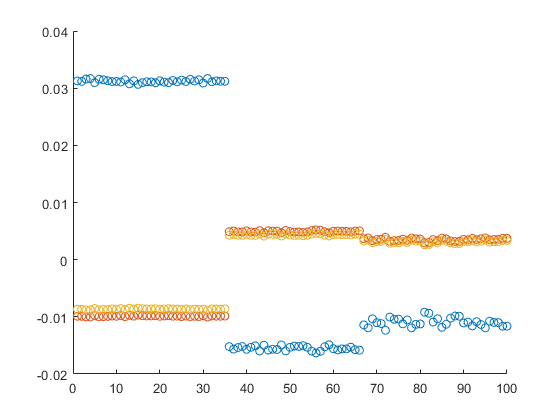


zy = z2; % B*w;
ay = p1;

% ay = (1+exp(-zy)).^-1;

zet=[];
zet(indexes(1:batchsize),:)=zy(1:end,:)';
zet = zet(any(zet,2),:);
scatter(1:batchsize,zet(:,1))
hold on
scatter(1:batchsize,zet(:,2))
scatter(1:batchsize,zet(:,3))
hold off

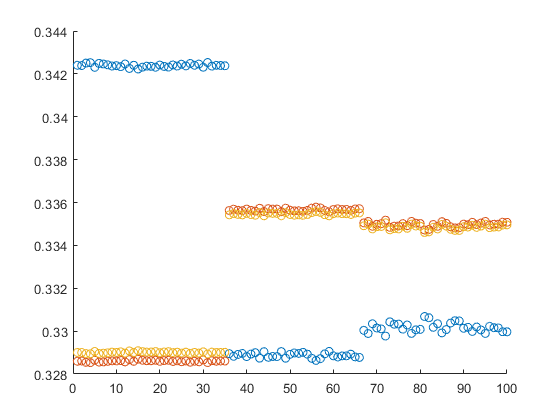


zet=[];
zet(indexes(1:batchsize),:)=ay(1:end,:)';
zet = zet(any(zet,2),:);
scatter(1:batchsize,zet(:,1))
hold on
scatter(1:batchsize,zet(:,2))
scatter(1:batchsize,zet(:,3))
hold off

% TEST set


% Vandermonde ----------test
Btest=[]


Btest =

     []



for i = 1:50

a=testinput(i,1).^[0:n];   a = a/norm(a);
b=testinput(i,2).^[0:n];   b = b/norm(b);
c=testinput(i,3).^[0:n];   c = c/norm(c);
d=testinput(i,4).^[0:n];   d = d/norm(d);

f= outproduct(a,b,c,d);
%     
% f= outproduct(testinput(i,1).^[0:n],testinput(i,2).^[0:n],testinput(i,3).^[0:n], testinput(i,4).^[0:n]);


Btest(i,:)=f(:)';
end

z1 = Btest*w;
zytest = w2*z1';
zytest = zytest'

zytest =     0.0333   -0.0106   -0.0093
    0.0341   -0.0109   -0.0096
    0.0353   -0.0113   -0.0099
    0.0498   -0.0159   -0.0136
   -0.0057    0.0018    0.0018
   -0.0238    0.0076    0.0066
   -0.0103    0.0033    0.0030
    0.0340   -0.0108   -0.0095
    0.0285   -0.0090   -0.0080
   -0.0154    0.0049    0.0044



exppy = exp(zytest-max(zytest,[],2));
pytest = exppy./sum(exppy,2);

% aytest = (1+exp(-zytest)).^-1;

[M, I] = max(pytest,[],2); 

misclassif = ~(I==ic(indexes((end-49):end)));
sum(abs(misclassif))/50

ans = 0.3000

sum(abs(pytest-testoutput), 'all')/(50)

ans = 1.3251


C = confusionmat(I,ic(indexes((end-49):end)))

C =     15     1     1
     0    18    13
     0     0     2


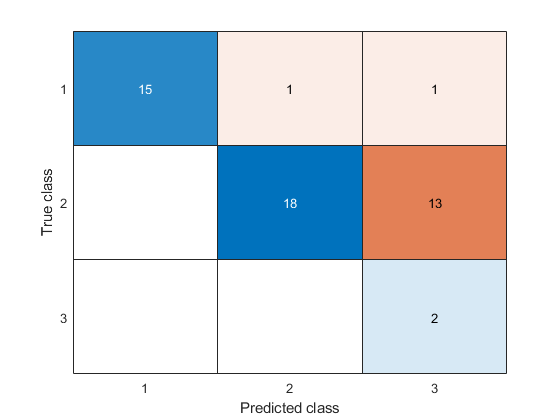

confusionchart(C);

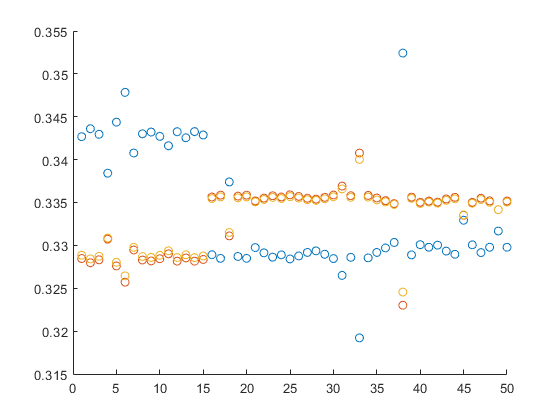


% scatter(1:50,misclassif);

zet=[];
zet(indexes((end-49):end),:)=pytest(1:end,:);
zet = zet(any(zet,2),:);
scatter(1:50,zet(:,1))
hold on
scatter(1:50,zet(:,2))
scatter(1:50,zet(:,3))
hold off



% rataa = norm(y-output)/norm(output)